# Homework 2

Lin Zhao, Ning Wang

## Exercise 1:Backstepping

### Open loop control

**1.1 **The key steps of the design should be described and the final controller equation should be given. (Hint: You don’t need to start with $y^{2}$ and do backstepping in three steps, you can consider $b_{3}y_{3}+y_{3}^{2}$ as input to a 2-dimensional linear system and apply backstepping from there.)

**Solution: **

Step 1: $K=b_{3}y_{3}+y_{3}^{2}$

Let $y_{2}=\phi_{1}(y_{1})=-k_{1}y_{1}$


$$z_{2}=y_{2}-\phi_{1}(y_{1})=y_{2}+k_{1}y_{1}$$



$$\dot{y}_{1}=-k_{1}y_{1}+z_{2}$$



$$\dot_{z}_{2}=\dot_{y}_{2}-\dot_{\phi_{1}}(y_{1})\\=-y_{1}-b_{2}y_{2}+K+k_{1}y_{2}$$


Let $V_{1}=\frac{y_{1}^{2}}{2}+\frac{z_{2}^{2}}{2}$

then we can get


$$\dot_{V}_{1}=y_{1}(-k_{1}y_{1}+z_{2})+z_{2}(-y_{1}-b_{2}y_{2}+K+k_{1}y_{2})\\=-k_{1}y_{1}^{2}+z_{2}(-b_{2}y_{2}+K+k_{1}y_{2})$$


Now that $-k_{1}y_{1}^{2}$ is negative definite, to make $\dot_{V}_{1}$ negative definite, we make the remaining term equal to $-k_{2}z_{2}^{2}$:


$$-k_{2}z_{2}=-b_{2}y_{2}+K+k_{1}y_{2}$$



$$K=-k_{2}z_{2}+b_{2}y_{2}-k_{1}y_{2}$$


Step 2:


$$\phi_{2}(y_{1},y_{2})=-k_{2}z_{2}+b_{2}y_{2}-k_{1}y_{2}\\=-k_{2}y_{2}-k_{1}k_{2}y_{1}+b_{2}y_{2}-k_{1}y_{2}$$



$$z_{3}=K-\phi_{2}(y_{1},y_{2})$$



$$V=V_{1}+\frac{z_{3}^{2}}{2}$$



$$\dot_{V}=\dot_{V_{1}}+z_{3}(\dot_{K}-\dot_{\phi}_{2})\\=\dot_{V_{1}}+z_{3}[(b_{3}+2y_{3})\dot_{y}_{3}+k_{1}k_{2}\dot_{y}_{1}+(k_{1}+k_{2}-b_{2})\dot_{y}_{2}]$$


Now that $\dot_{V_{1}}$ is negative definite, to make $\dot_{V}$ negative definite, we make the remaining term equal to $-k_{3}z_{3}^{2}$:


$$-k_{3}z_{3}=(b_{3}+2y_{3})\dot_{y}_{3}+k_{1}k_{2}\dot_{y}_{1}+(k_{1}+k_{2}-b_{2})\dot_{y}_{2}$$



$$\dot_{y}_{3}=\frac{-k_{3}z_{3}-k_{1}k_{2}\dot_{y}_{1}-(k_{1}+k_{2}-b_{2})\dot_{y}_{2}}{b_{3}+2y_{3}}$$



$$v=\frac{-k_{3}z_{3}-k_{1}k_{2}\dot_{y}_{1}-(k_{1}+k_{2}-b_{2})\dot_{y}_{2}}{b_{3}+2y_{3}}-c_{1}y_{1}-c_{3}y_{3}-c_{13}y_{1}y_{3}$$


close all
clear
clc

k1=0.5;
k2=3.2;
k3=0.6;
x1s=0.6; % x1 star 0.6
x3s=x1s^0.5; % x3 star 
x2s=0;
b=0.2;
c=2.6;
b2=b;
b3=2*x3s;
c1=c*x3s;
c3=c*(x1s-1);
c13=c;
tf=20;
us=c*(1-x1s)*sqrt(x1s); % the value of u star
f1=@(y2) y2;
f2=@(y1,y2,y3) -y1-b2*y2+b3*y3+y3.^2;
%f3=@(y1,y3,v) c1*y1+c3*y3+c13*y1.*y3+mysaturation(v,-1000,1000);
f3=@(y1,y3,v) c1*y1+c3*y3+c13*y1.*y3+v;
f=@(y1,y2,y3,v) [f1(y2);f2(y1,y2,y3);f3(y1,y3,v)];
z2=@(y1,y2) k1*y1+y2; % 改动
k=@(y3) b3*y3+y3.^2;
phi=@(y1,y2,z2) (k1-k2)*z2+b2*y2-k1^2*y1; % 改动
z3=@(k,phi) k-phi;
Dy1=@(y2) y2; %改动
Dy2=@(y1,y2,y3) -y1-b2*y2+b3*y3+y3.^2;
Dy3=@(y3,z3,Dy1,Dy2) ((-k1-k2+b2)*Dy2-k3*z3-k1*k2*Dy1)./(b3+2*y3);% 改动 again +dv/y2
v=@(y1,y3,Dy3) Dy3-c1*y1-c3*y3-c13*y1.*y3;

**1.2 **Tune the controller parameters so that |𝑢(𝑡)|≤2 when $x(0)=[0.1,0,\sqrt{0.1}]$. Comment on the tuning procedure and give the values of the final design.

**Solution:**

In the final design, the values are shown below:


$$k_{1}=0.5\\k_{2}=3.2\\k_{3}=0.6$$


When $x(0)=[0.1,0,\sqrt{0.1}]$, the results are shown in figure 1. It can be shown that after a period of adjustment, $x_{1}$, $x_{2}$ and $x_{3}$ will be stabilized at the equilibrium point. As is shown in figure 2,$|u(t)|<2$ holds in the whole procedure, which meets the requirements of the task.  

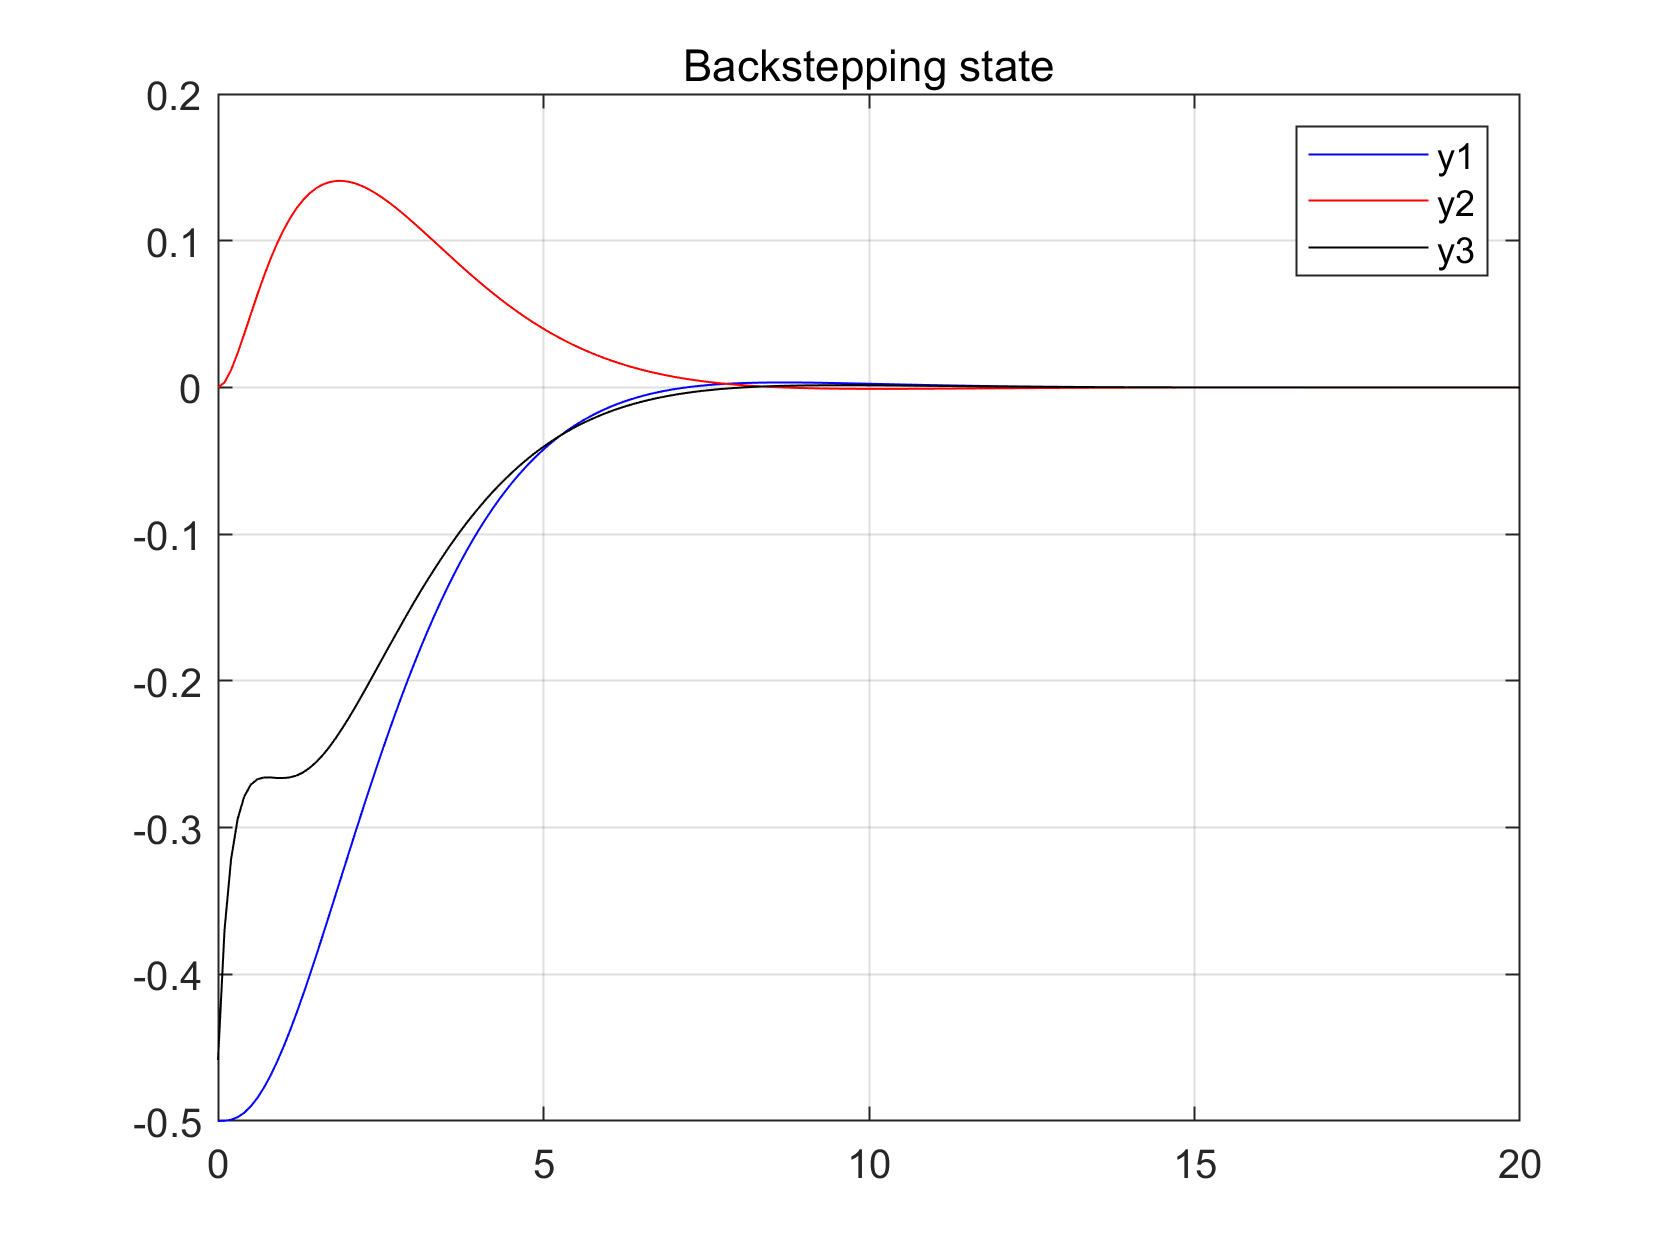

x0=[0.1;0;sqrt(0.1)];
y0=[x0(1)-x1s;x0(2)-x2s;x0(3)-x3s];

sol=ode45(@(t,y)f(y(1),y(2),y(3),v(y(1),y(3),Dy3(y(3),z3(k(y(3)),phi(y(1),y(2),z2(y(1),y(2)))),Dy1(y(2)),Dy2(y(1),y(2),y(3))))), [0,tf], y0);
t=linspace(0,tf,200);
y=deval(sol,t);
v1(:)=v(y(1,:),y(3,:),Dy3(y(3,:),z3(k(y(3,:)),phi(y(1,:),y(2,:),z2(y(1,:),y(2,:)))),Dy1(y(2,:)),Dy2(y(1,:),y(2,:),y(3,:))));
figure(1)
plot(t,y(1,:),'-b');
hold on
plot(t,y(2,:),'-r');
hold on
plot(t,y(3,:),'-k');
legend('y1','y2','y3')
title('Backstepping state')
grid on

Figure 1. Output of $y_{1}$, $y_{2}$ and $y_{3}$ with initial value $x(0)=[0.1,0,\sqrt{0.1}]$.

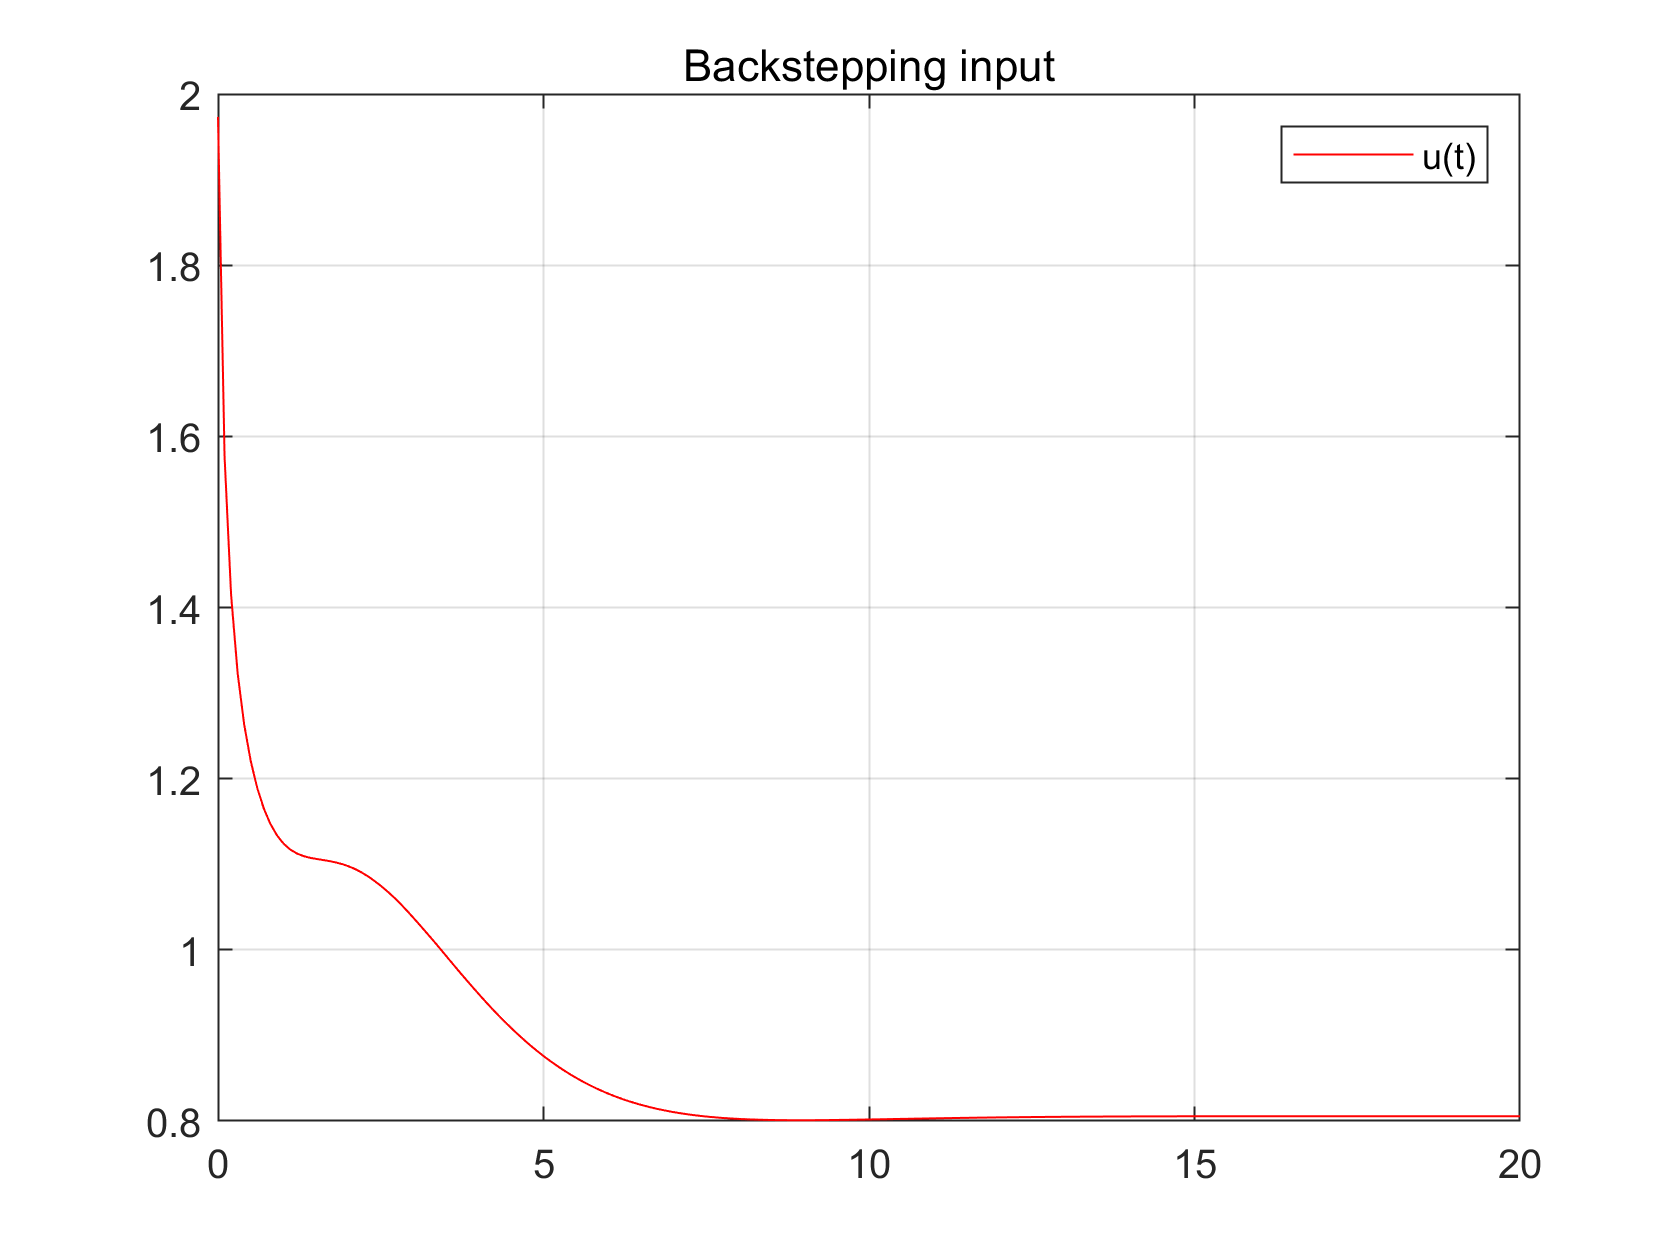

figure(2)
plot(t,v1(:)+us,'-r');
legend('u(t)')
title('Backstepping input')
grid on

% figure(2)
% for a = 1:200
%     u(a)=c*(1-x1s)*x1s^0.5+f3(y(1,a),y(3,a),v(y(1,a),y(3,a),Dy3(y(3,a),z3(k(y(3,a)),phi(y(1,a),y(2,a),z2(y(1,a),y(2,a)))),Dy1(y(2,a)),Dy2(y(1,a),y(2,a),y(3,a)))))-c1*y(1,a)-c3*y(3,a)-c13*y(1,a).*y(3,a);
% end
% %v1(:)=f3(y(1,:),y(3,:),v(y(1,:),y(3,:),Dy3(y(3,:),z3(k(y(3,:)),phi(y(1,:),y(2,:),z2(y(1,:),y(2,:)))),Dy1(y(2,:)),Dy2(y(1,:),y(2,:),y(3,:)))))-c1*y(1,:)-c3*y(3,:)-c13*y(1,:).*y(3,:)
% plot(t,u(:));
% legend('u');

Figure 2. Variation of the initial control input $u$ with initial value $x(0)=[0.1,0,\sqrt{0.1}]$.

In tuning, we find that the larger $k_{1}$, $k_{2}$ and $k_{3}$ are, the faster $x_{1}$, $x_{2}$ and $x_{3}$ will converge at the equilibirum point. But larger values for $k_{1}$, $k_{2}$ and $k_{3}$ also result in a larger initial control input $u$. We tried to make $k_{1}$ large but the state variables failed to converge in the set time. Then we set a small value for $k_{1}$ and tried on $k_{2}$ and $k_{3}$. Firstly we made both large to guarantee a fast control, then we tried to lower these values to meet the requirement on the adsolute value of $u$ and found that to lower $k_{3}$ is more effective in reducing the initial value of $u$ and affects the converge time less.

**1.3 **Simulate the system under feedback control. Study initial states of the form $x(0)=[x_{1}(0),0,\sqrt{x_{1}(0)}]$ and vary $x_{1}(0)$ between 0 and 1. Remember to plot the original state  $x_{1}(t)$ and not $y_{1}(t)$. Comment on the performance and the region of attraction.

**Solution:**

In this section, the system is verifified for different initial states. Make $x_{1}(0)$ go from 0 to 1, and set initial states in the form $x(0)=[x_{1}(0),0,\sqrt{x_{1}(0)}]$. We set $x_{1}(0)$ every 0.1 from 0 to 1, and get the output result as shown in figure 3. It can be seen from the figure that the system will converge at the equilibrium point $x_{1}=0.6$, $x_{2}=0$ and $x_{3}=\sqrt{0.6}$ after a period of adjustment for every initial state in this range. So at least $0 <x_{1}(0) \leq 1$ is in the region of attraction.

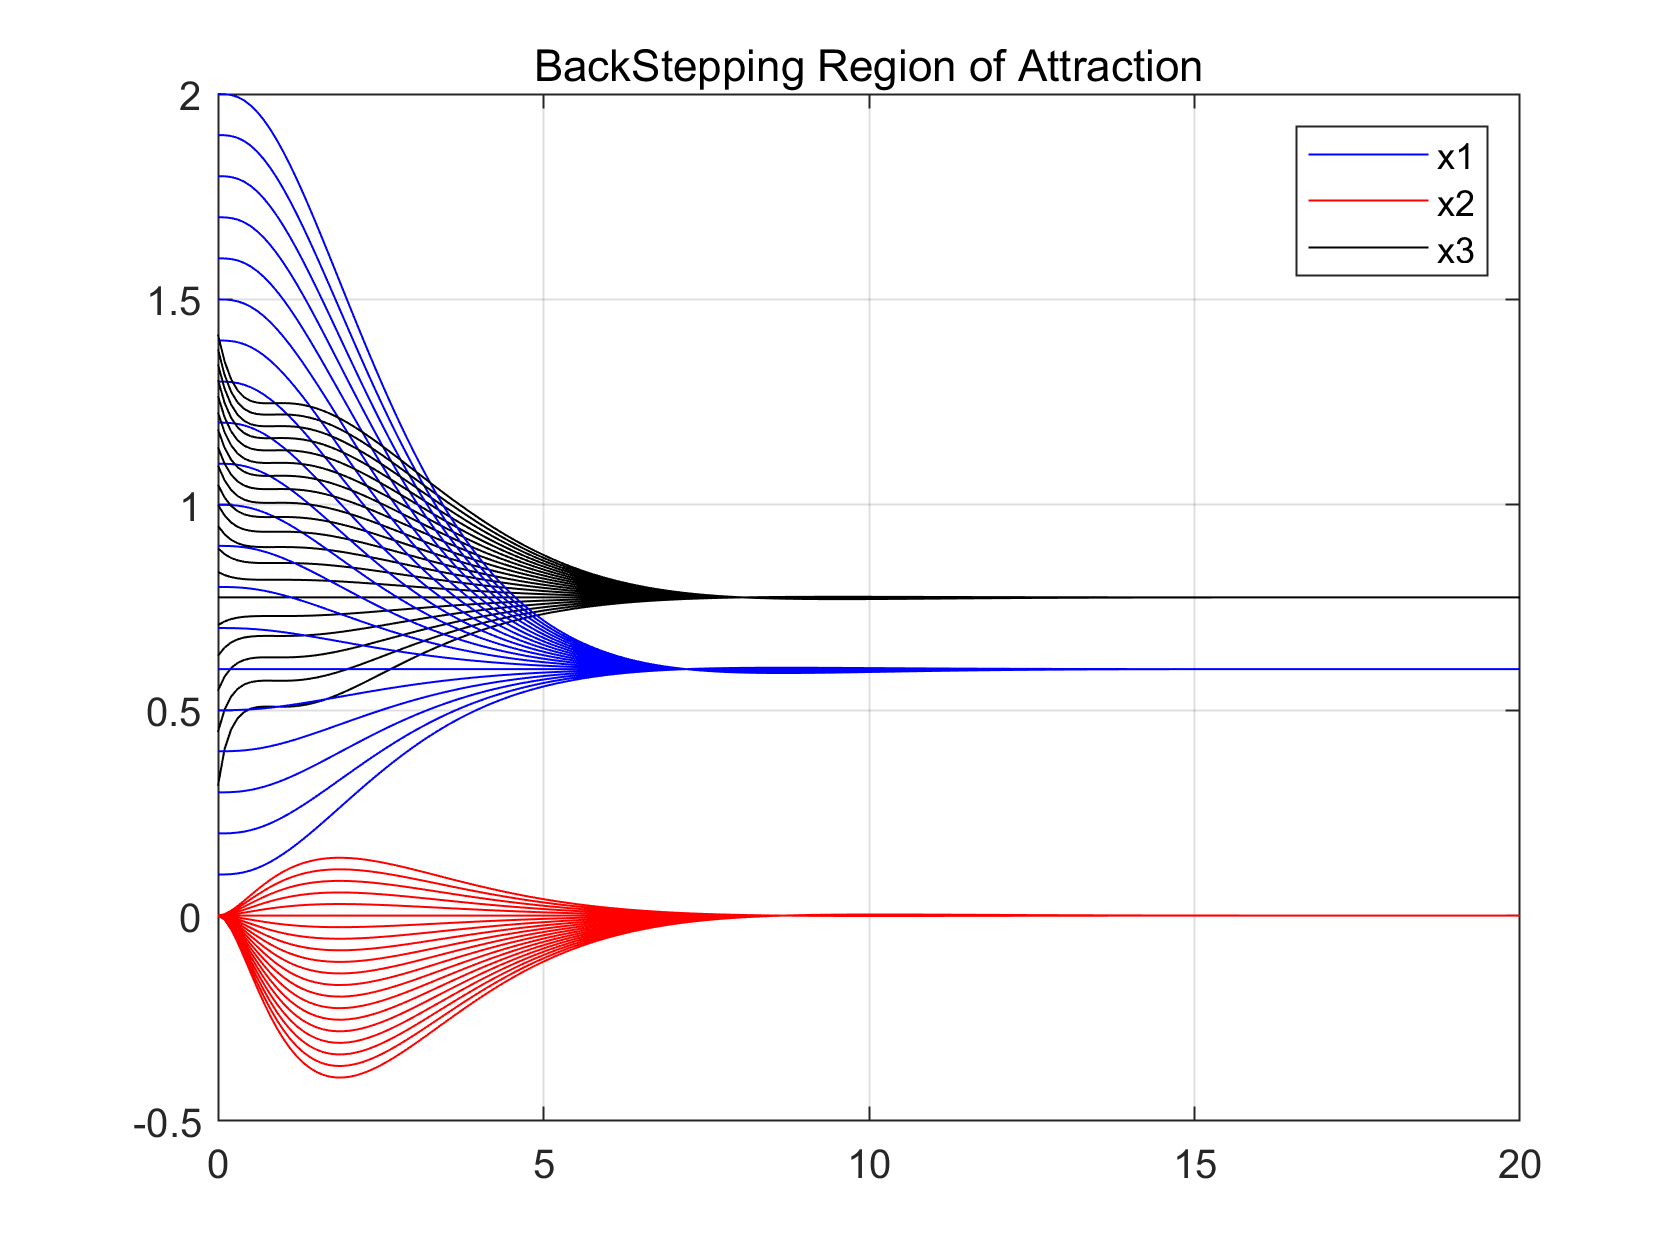

figure(3)
for i = 0:0.1:2
    y0 = [i-x1s, 0.0, i^0.5-x1s^0.5]';
    sol=ode45(@(t,y)f(y(1),y(2),y(3),v(y(1),y(3),Dy3(y(3),z3(k(y(3)),phi(y(1),y(2),z2(y(1),y(2)))),Dy1(y(2)),Dy2(y(1),y(2),y(3))))), [0,tf], y0);
    t=linspace(0,tf,200);
    y=deval(sol,t);
    plot(t,y(1,:)+x1s,'-b')
    hold on
    plot(t,y(2,:),'-r')
    hold on
    plot(t,y(3,:)+x1s^0.5,'-k')
    hold on
    legend('x1','x2','x3')
    title('BackStepping Region of Attraction')
    hold on   
    grid on
end

Figure 3. Output of $x_{1}$, $x_{2}$ and $x_{3}$ with different initial value(back stepping).

## Exercise 2. Controller Comparison

Comare the three feedback controllers from homework 1.1 and Homework 1.2. Linearization, Feedback Linearization and Backsteepping.

**2.1 **Comment on advantages and disadvantages.

**Solution:**

(1). The advantages of backsteeping compared with Linearization and Feedback Linearization: 1.  Compared with Linearization and Feedback Linearization, the Backstepping model is more accurate, because it does not have the linearization process, so the model error is small.  2.  For the Linearization and feedback Linearization, the LQR weight matric is difficult to design sometimes.  3.  Because of the Lyapunuov function, the system states will converge soon and there are little vibration, it will be stable in a smooth way. 

(2). Disadvantages of Backstepping: 1. In the backstepping method, there are not as much as methods for analysing the system stability, such as equilibrium point analysing.   2. Because of the influence of denominator (sometimes will be 0), the input will become infinity, so the controller wil breaksown immediately.  3. The calculation amount of Bacstepping is large, if there are multi-dimensional system, it may difficulty to calculate and have a higher requirement for the PC.   

**2.2 **Comment on performance and region of attraction.

**Solution:**

Comment on performance : From figure 6 and figure 7 , we can find that backstepping and feedback linearization control have the similar speed to converge, while the feedback linearization have more vibration. For the linearzation, it will converge slower than the backstepping and feedback linearization. For the input u(t), we can see that the input of feedback linearization have a bigger value than the other two controller. While the backstepping and linearization have the similar input.   By analysing the system state and input, we can conclude that the backstepping have a better control effect.

Comment on Region of attration: From figure 3, 4, 5 we can see the system state with different initial values. for the backstepping and feedback linearization, we change the initial value of x(0)=(x1(0), 0, sqrt(x1(0))), and x1(0)=0:0.1: 2.  The system is stable is this range. so the value of x1(0) between [0, 2] is in the region of attraction. While for the linearization, when the x1(0) bigger than 1, the system will become unstable as shown in figure(5), so the region of attraction of linearization control is between  [0,1].

**2.3 **Comment on the tuning procedure.

**Solution:**

 (1) Tuning procedure of backstepping: In the tuning of backstepping, we find that the larger $k_{1}$, $k_{2}$ and $k_{3}$ are, the faster $x_{1}$, $x_{2}$ and $x_{3}$ will converge to the equilibirum point. But larger values for $k_{1}$, $k_{2}$ and $k_{3}$ also result in a larger initial control input $u$. Firstly we made $k_{1}$ large but the state variables failed to converge in the set time. Then we set small values for $k_{1}$ and tried to tune $k_{2}$ and $k_{3}$. Firstly we made both large to guarantee a fast control, then we tried to lower these values to meet the requirement on the adsolute value of $u$ and found that to lower $k_{3}$ is more effective in reducing the initial value of $u$ and affects the converge time less. Sometimes there is a doninator in the expression of the control input, to avoid NaN when the dominator becomes zero we apply a saturation and the upper and lower bound for the control input also need to be tuned. In summary, the number of parameters to be tuned depends on the dimension of the system(or the number of steps), and it isn't too difficult to get a effective controller.

(2）Tuning procedure of feedback linearization: In the tuning of feedback linearization, we firstly set the Q=eye(3), which guarantee the each state have the same weight. We mainly focus on tuning the value of R, the large R will generate smaller  input(u(t)),  but the control state of x(t) will become bad, converge slowly and more vibration. so we just trade of the input and system state, to gurantee a stable input and system state.

(3) Tuning procedure of linearization: In the tuning of linearization, we use the pole placement method to design the controller. To choose poles is something called "art" as both the real and imaginary parts need to be tuned. Poles far from the imaginary axis result in larger region of attraction but the initial control input becomes large, which might be out of the required range. Poles too far from the real axis make the state variables fail to converge.

- Plot x1(t) and u(t) using the three controller, starting  from x(0)=0.

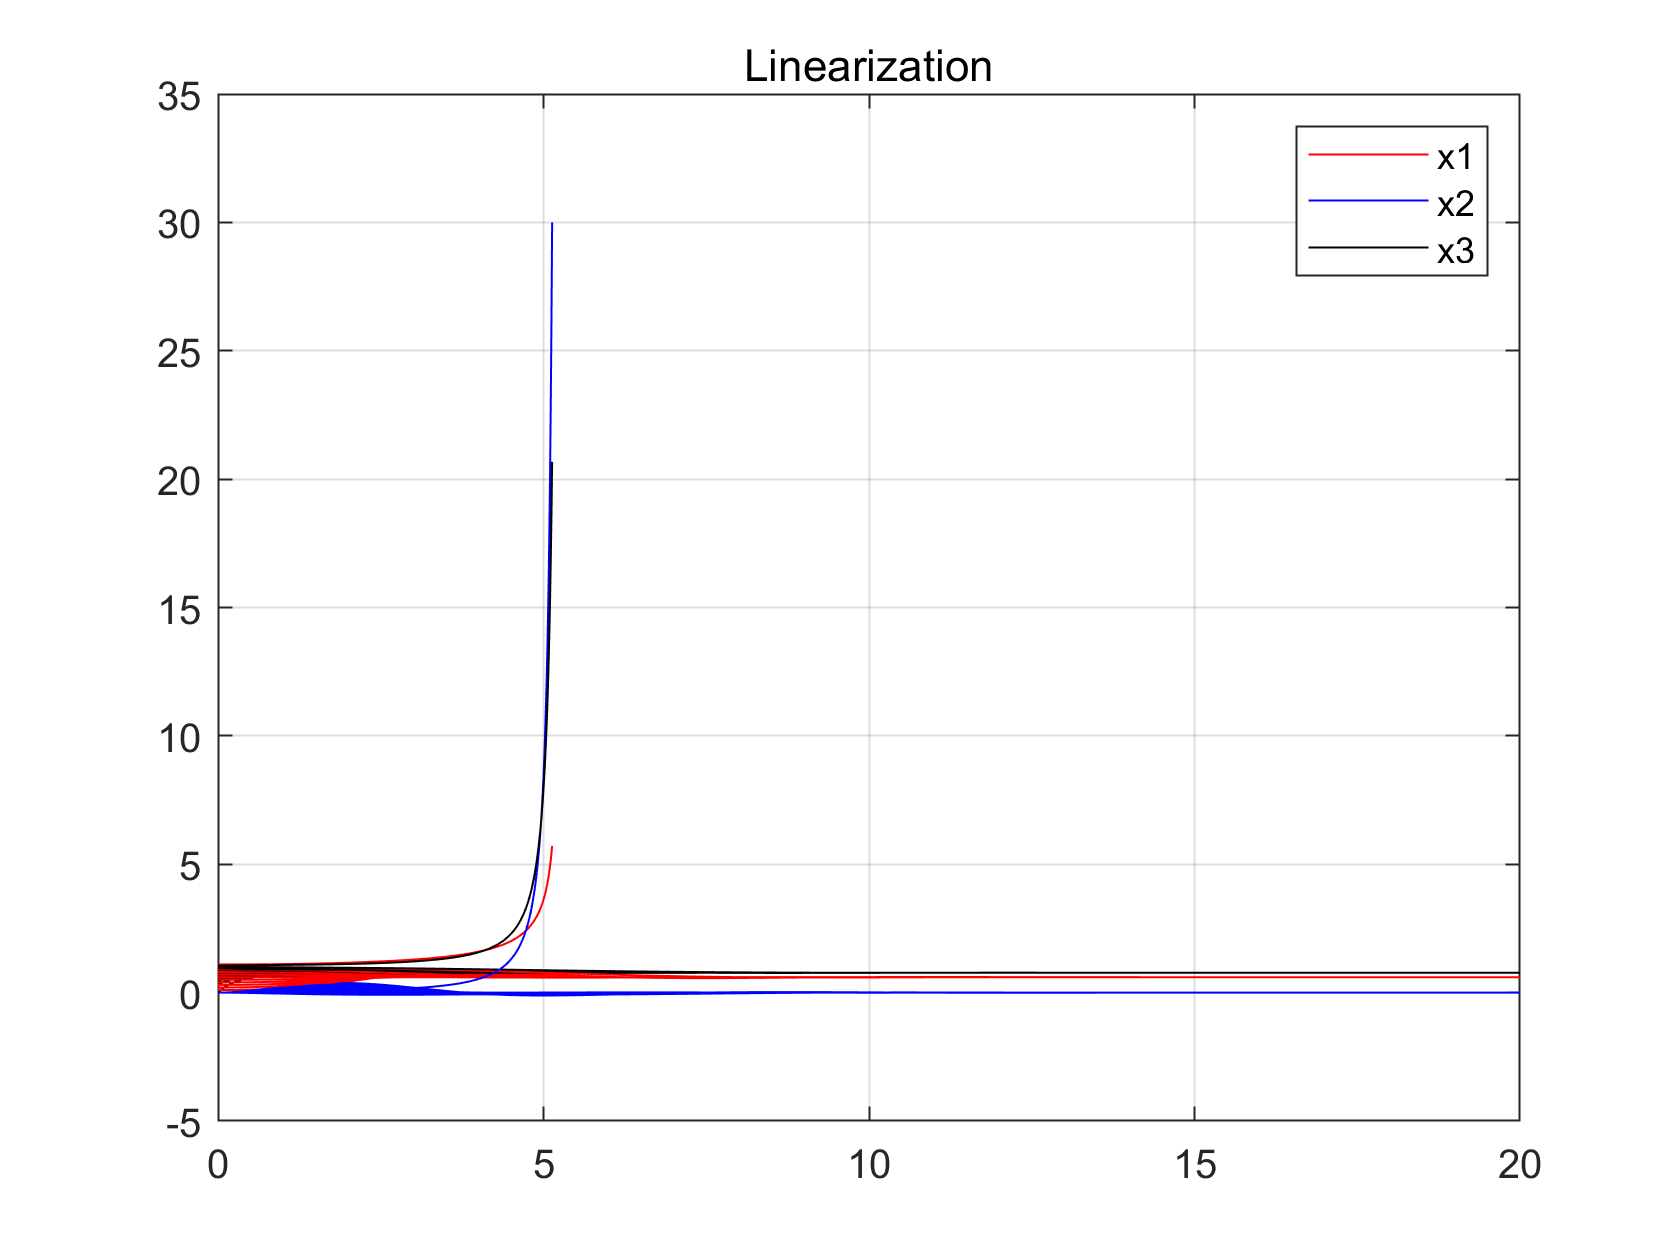

%% matlab Function of backstepping

clear

k1=0.5;
k2=3.2;
k3=0.6;
x0=[0;0;0];
x1s=0.6; % x1 star 0.6
x3s=x1s^0.5; % x3 star 
x2s=0;
b=0.2;
c=2.6;
b2=b;
b3=2*x3s;
c1=c*x3s;
c3=c*(x1s-1);
c13=c;
tf=20;
us=c*(1-x1s)*sqrt(x1s); % the value of u star
f1=@(y2) y2;
f2=@(y1,y2,y3) -y1-b2*y2+b3*y3+y3.^2;
f3=@(y1,y3,v) c1*y1+c3*y3+c13*y1.*y3+mysaturation(v,-1,1);
%f3=@(y1,y3,v) c1*y1+c3*y3+c13*y1.*y3+v;
f=@(y1,y2,y3,v) [f1(y2);f2(y1,y2,y3);f3(y1,y3,v)];
z2=@(y1,y2) k1*y1+y2; % 改动
k=@(y3) b3*y3+y3.^2;
phi=@(y1,y2,z2) (k1-k2)*z2+b2*y2-k1^2*y1; % 改动
z3=@(k,phi) k-phi;
Dy1=@(y2) y2; %改动
Dy2=@(y1,y2,y3) -y1-b2*y2+b3*y3+y3.^2;
Dy3=@(y3,z3,Dy1,Dy2) ((-k1-k2+b2)*Dy2-k3*z3-k1*k2*Dy1)./(b3+2*y3);% 改动 again +dv/y2
v=@(y1,y3,Dy3) Dy3-c1*y1-c3*y3-c13*y1.*y3;
y0=[x0(1)-x1s;x0(2)-x2s;x0(3)-x3s];
sol=ode45(@(t,y)f(y(1),y(2),y(3),v(y(1),y(3),Dy3(y(3),z3(k(y(3)),phi(y(1),y(2),z2(y(1),y(2)))),Dy1(y(2)),Dy2(y(1),y(2),y(3))))), [0,tf], y0);

t=linspace(0,tf,200);
y1=deval(sol,t);
v1(:)=v(y1(1,:),y1(3,:),Dy3(y1(3,:),z3(k(y1(3,:)),phi(y1(1,:),y1(2,:),z2(y1(1,:),y1(2,:)))),Dy1(y1(2,:)),Dy2(y1(1,:),y1(2,:),y1(3,:))));







% Linearization
syms x [3,1]
syms u
f1 = @(x1,x2,x3) x2;
f2 = @(x1,x2,x3) -x1-0.2*x2+2*sqrt(0.6).*x3 + x3.^2;
f3 = @(x1,x2,x3,u)  2.6*sqrt(0.6)*x1+2.6*(0.6-1)*x3+2.6.*x1.*x3+u;
f = @(x1,x2,x3,u)[f1(x1,x2,x3);f2(x1,x2,x3);f3(x1,x2,x3,u)];
A = double(subs(jacobian(f,x),x,[0;0;0]));
B = [0;0;1];
u0 = 2.6*(1-0.6)*0.6^0.5;
P = [-1.3;-0.4-0.9i;-0.4+0.9i];
Kv = place(A,B,P);
u = @(x1,x2,x3) -Kv(1)*x1 -Kv(2)*x2-Kv(3)*x3;

%x0 = [0.4;0.4;0.4];
tf = 20;
event_out = @(varargin) varargin{:};
x_lim = 30;
out_of_bounds = @(t,x) event_out(max(abs(x))-x_lim,1,1);
options = odeset('Events',out_of_bounds);
% for i=0:0.1:1
x0 = [0-0.6, 0, 0-0.6^0.5]';
sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
t = linspace(0,sol.x(end),200);
y2 = deval(sol,t);


v2(:) = u(y2(1,:),y2(2,:),y2(3,:));

figure(10)

for i = 0:0.1:1.1
    x0 = [i-0.6, 0.0, i^0.5-0.6^0.5]';
    sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
    t = linspace(0,sol.x(end),500);
    x = deval(sol,t);
    %subplot(2,1,1)
    title('Linearization')
    plot(t,x(1,:)+0.6,'-r')
    hold on
    plot(t,x(2,:),'-b')
    hold on
    plot(t,x(3,:)+0.6^0.5,'-k')
    hold on
    legend('x1','x2','x3')
    hold on   
    legend('x1','x2','x3')
    grid on
end

Figure 4. State of X in dfferent initial state (Linearization)

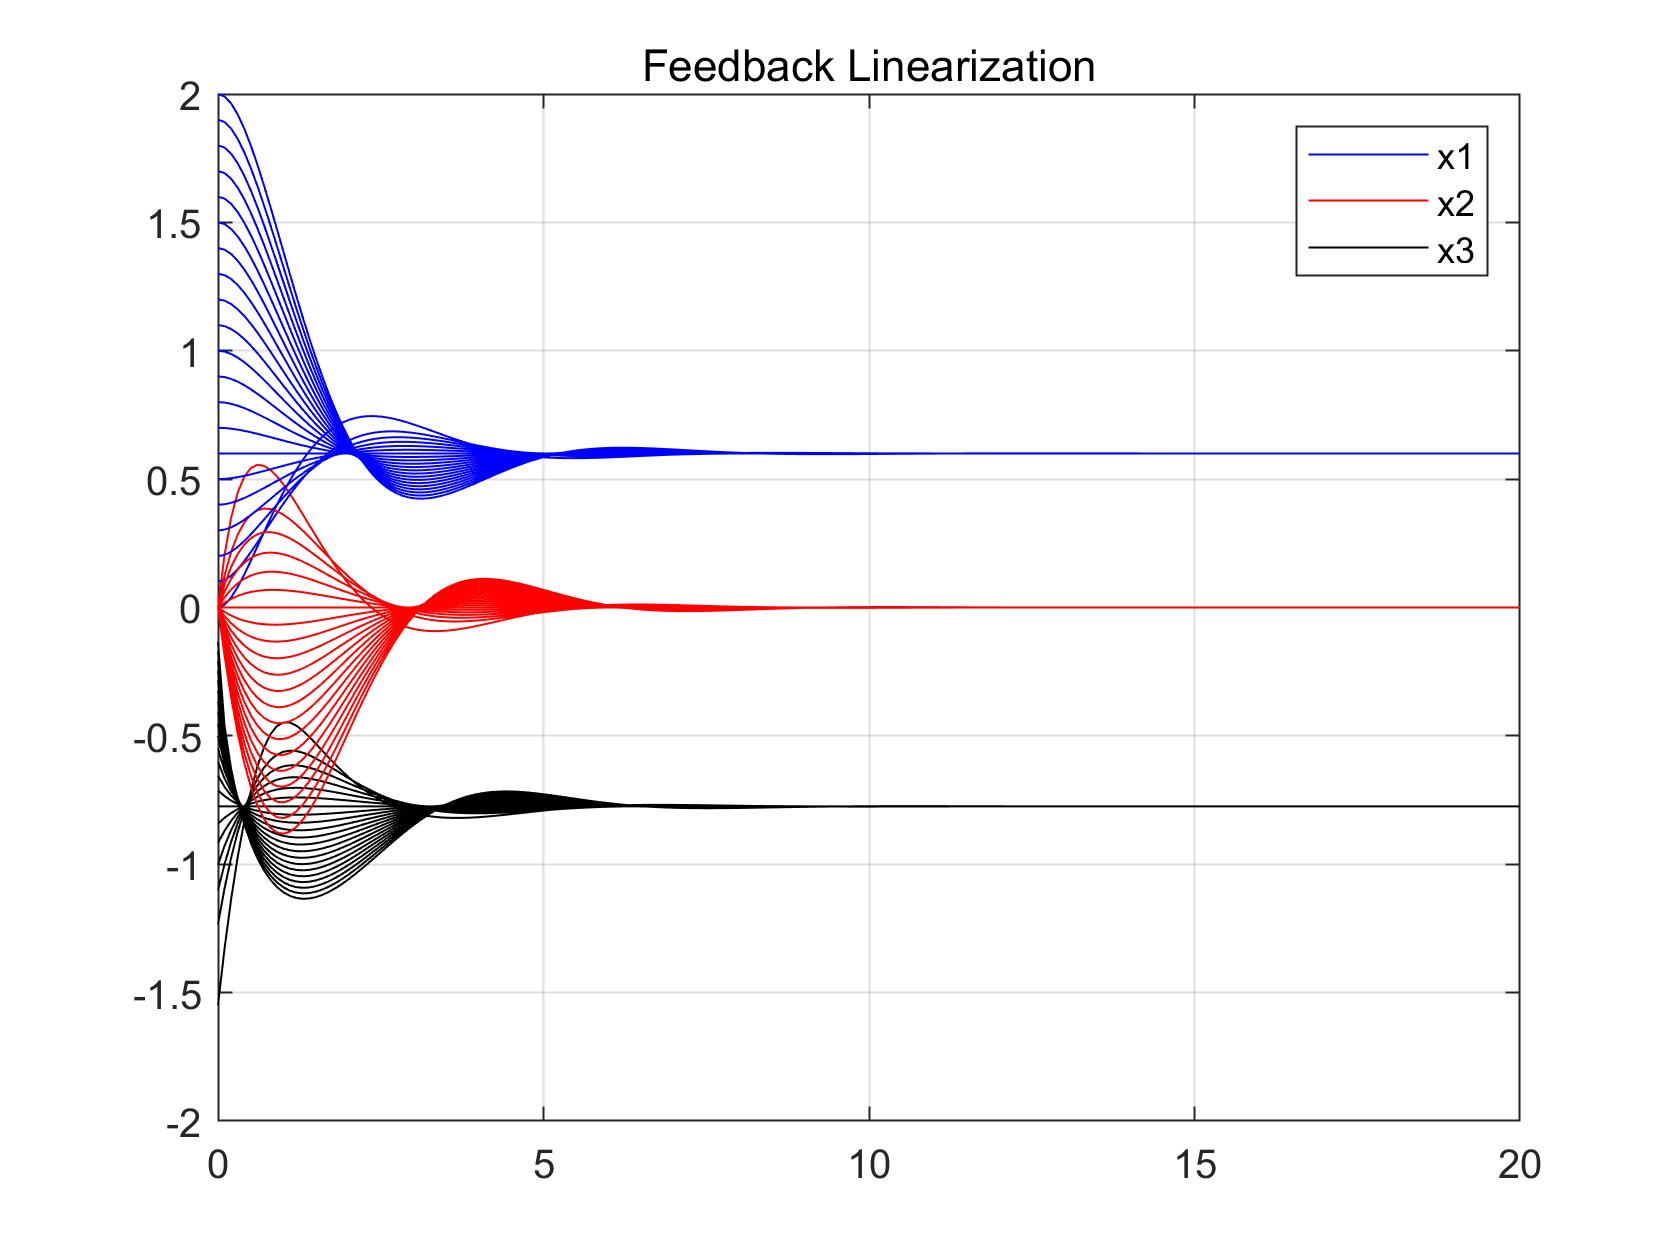

%Feedback Linearization

x1= 0.6;
x33=0.6^0.5;
x34=-0.6^0.5;
M31=[0  1   0;  -1   -0.2   2*x33;  2.6*x33  0  -2.6+2.6*x1];
M32=[0  1   0;  -1   -0.2   2*x34;  2.6*x34  0  -2.6+2.6*x1];
[V3,D3]=eig(M31);
[V4,D4]=eig(M32);
x1s=0.6;
x3s1=x1s^0.5; %x3*
x3s2=-x1s^0.5;
u1s=2.6*(1-x1s)*x3s1;
u2s=2.6*(1-x1s)*x3s2;
b2=0.2;
b31=2*x3s1;
b32=2*x3s2;
c11=2.6*x3s1;
c12=2.6*x3s2;
c3=2.6*(x1s-1);
c13=2.6;
f1 = @(x1,x2,x3) x2;
f2 = @(x1,x2,x3) -x1-b2*x2+b32.*x3 + x3.^2;
f3 = @(x1,x2,x3,u)  c12*x1+c3*x3+c13.*x1.*x3+u;
f = @(x1,x2,x3,u)[f1(x1,x2,x3);f2(x1,x2,x3);f3(x1,x2,x3,u)];
psi = @(x1,x2,x3)(b32+2.*x3).*(c12.*x1+c3.*x3+c13.*x1.*x3);
gamma = @(x1,x2,x3)(b32+2.*x3);
A =[0 1 0; -1 -0.2 1; 0  0  0];
B =[0; 0; 1];
Q = eye(3);
R = 0.1;
Kv = lqr(A,B,Q,R);
v = @(x1,x2,x3) -Kv(1)*x1 -Kv(2)*x2-Kv(3)*(b32*x3+x3.^2);
u_fbl = @(x1,x2,x3) 1./gamma(x1,x2,x3).*(-psi(x1,x2,x3)+v(x1,x2,x3));
%x0 = [0.4;0.4;0.4];
tf = 20;
event_out = @(varargin) varargin{:};
x_lim = 30;
out_of_bounds = @(t,x) event_out(max(abs(x))-x_lim,1,1);
options = odeset('Events',out_of_bounds);
    x0 = [0-0.6, 0, 0^0.5-0.6^0.5]';
     u = u_fbl;
 
    sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
    t = linspace(0,sol.x(end),200);
    x = deval(sol,t);
    y3=x;
    ga=gamma(x(1,:),x(2,:),x(3,:));
    v=v(x(1,:),x(2,:),x(3,:));
    psi=psi(x(1,:),x(2,:),x(3,:));
    v3 = 1./ga.*(-psi)+v;
   
   for i=0:0.1:2
    x0 = [i-0.6, 0, i^0.5-0.6^0.5]';
u = u_fbl;
 
    sol = ode45(@(t,x)f(x(1),x(2),x(3),u(x(1),x(2),x(3))),[0,tf],x0,options);
    t = linspace(0,sol.x(end),200);
    x = deval(sol,t);
    figure(7)
    title('Feedback Linearization') 
    plot(t,x(1,:)+0.6,'-b')
    hold on
    plot(t,x(2,:),'-r')
    hold on
    plot(t,x(3,:)-0.6^0.5,'-k')
    hold on
    legend('x1','x2','x3')
    grid on
%     subplot(2,1,2)
%     plot(t,u{:},(x(1,:),x(2
end

Figure 5. state of x in different initial value (Feedback Linearlization)

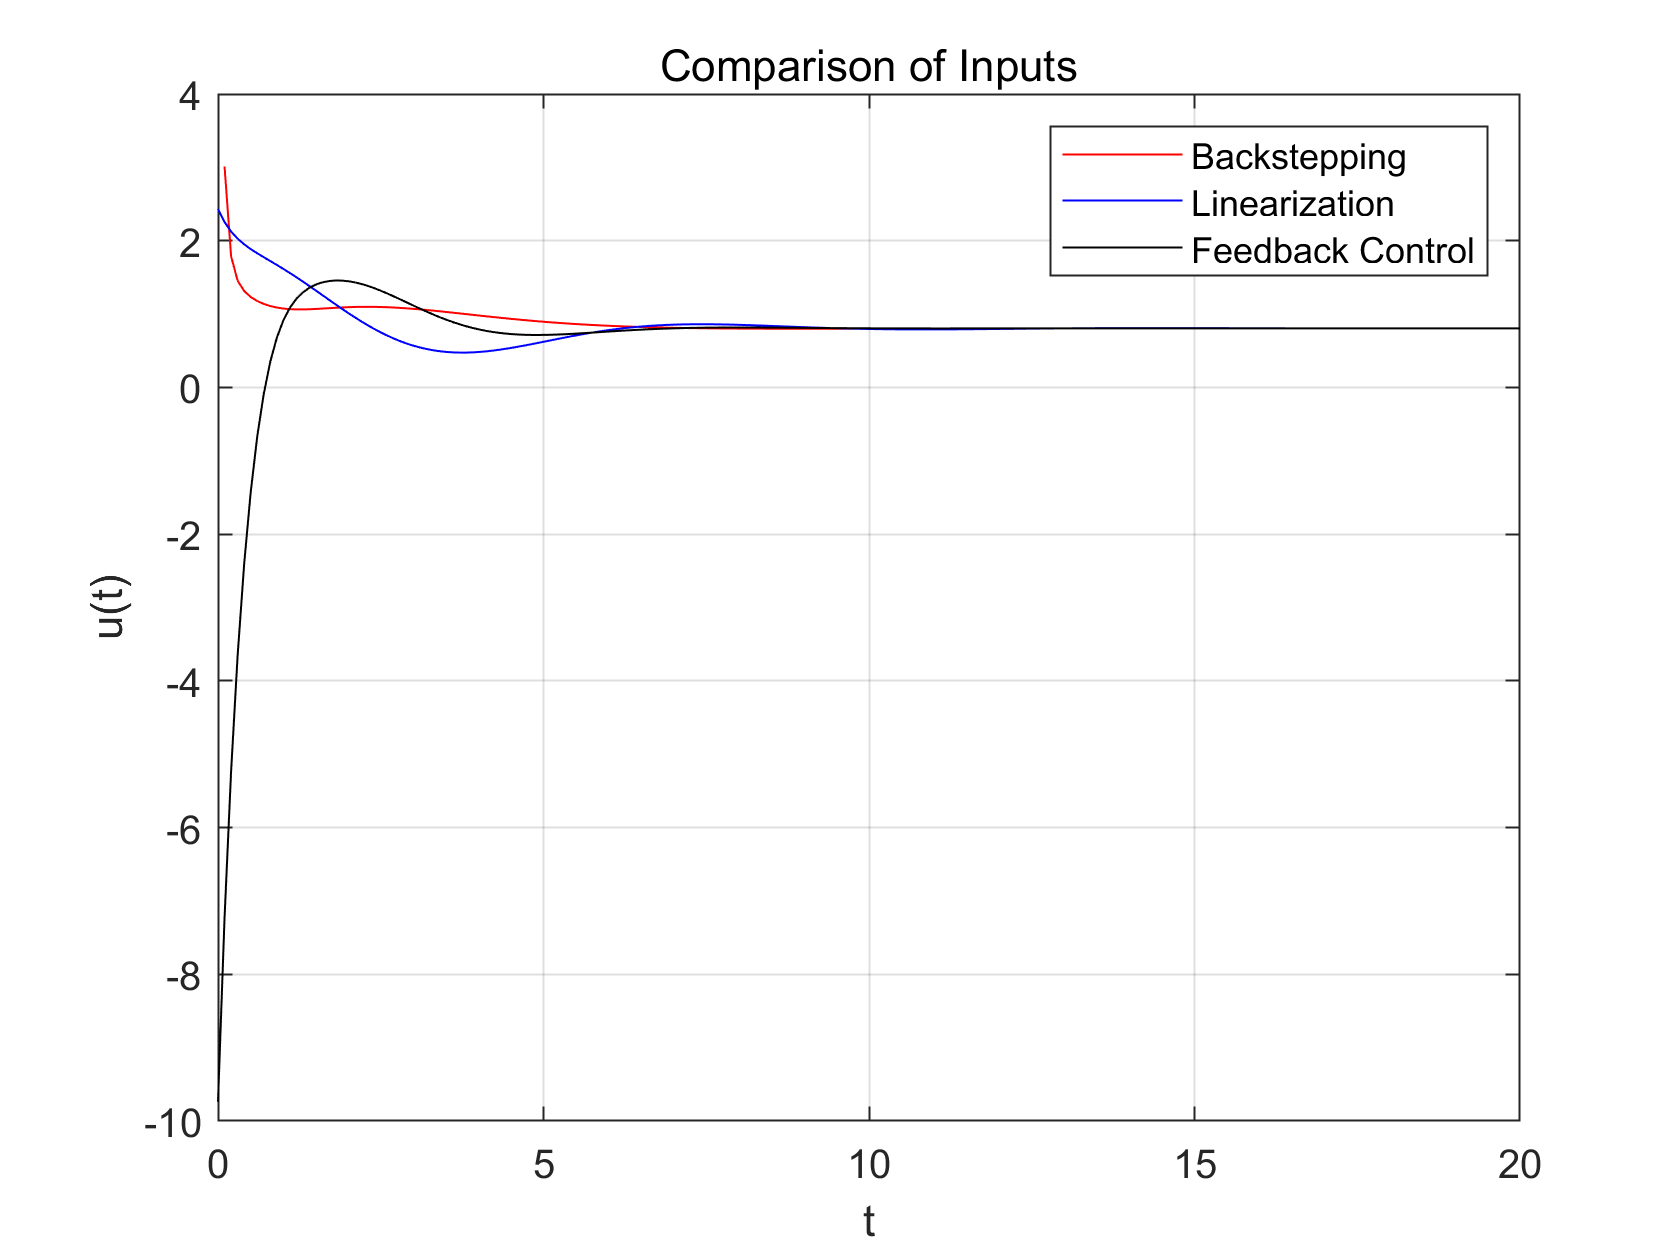

  % plot
figure(8)

plot(t,v1(1,:)+us,'-r')
hold on
plot(t,v2(1,:)+us,'-b')
hold on
plot(t,v3(1,:)+us,'-k')
legend('Backstepping','Linearization','Feedback Control')
title('Comparison of Inputs')
xlabel('t')
ylabel('u(t)')
grid on;

Figure 6. Comparsion of input

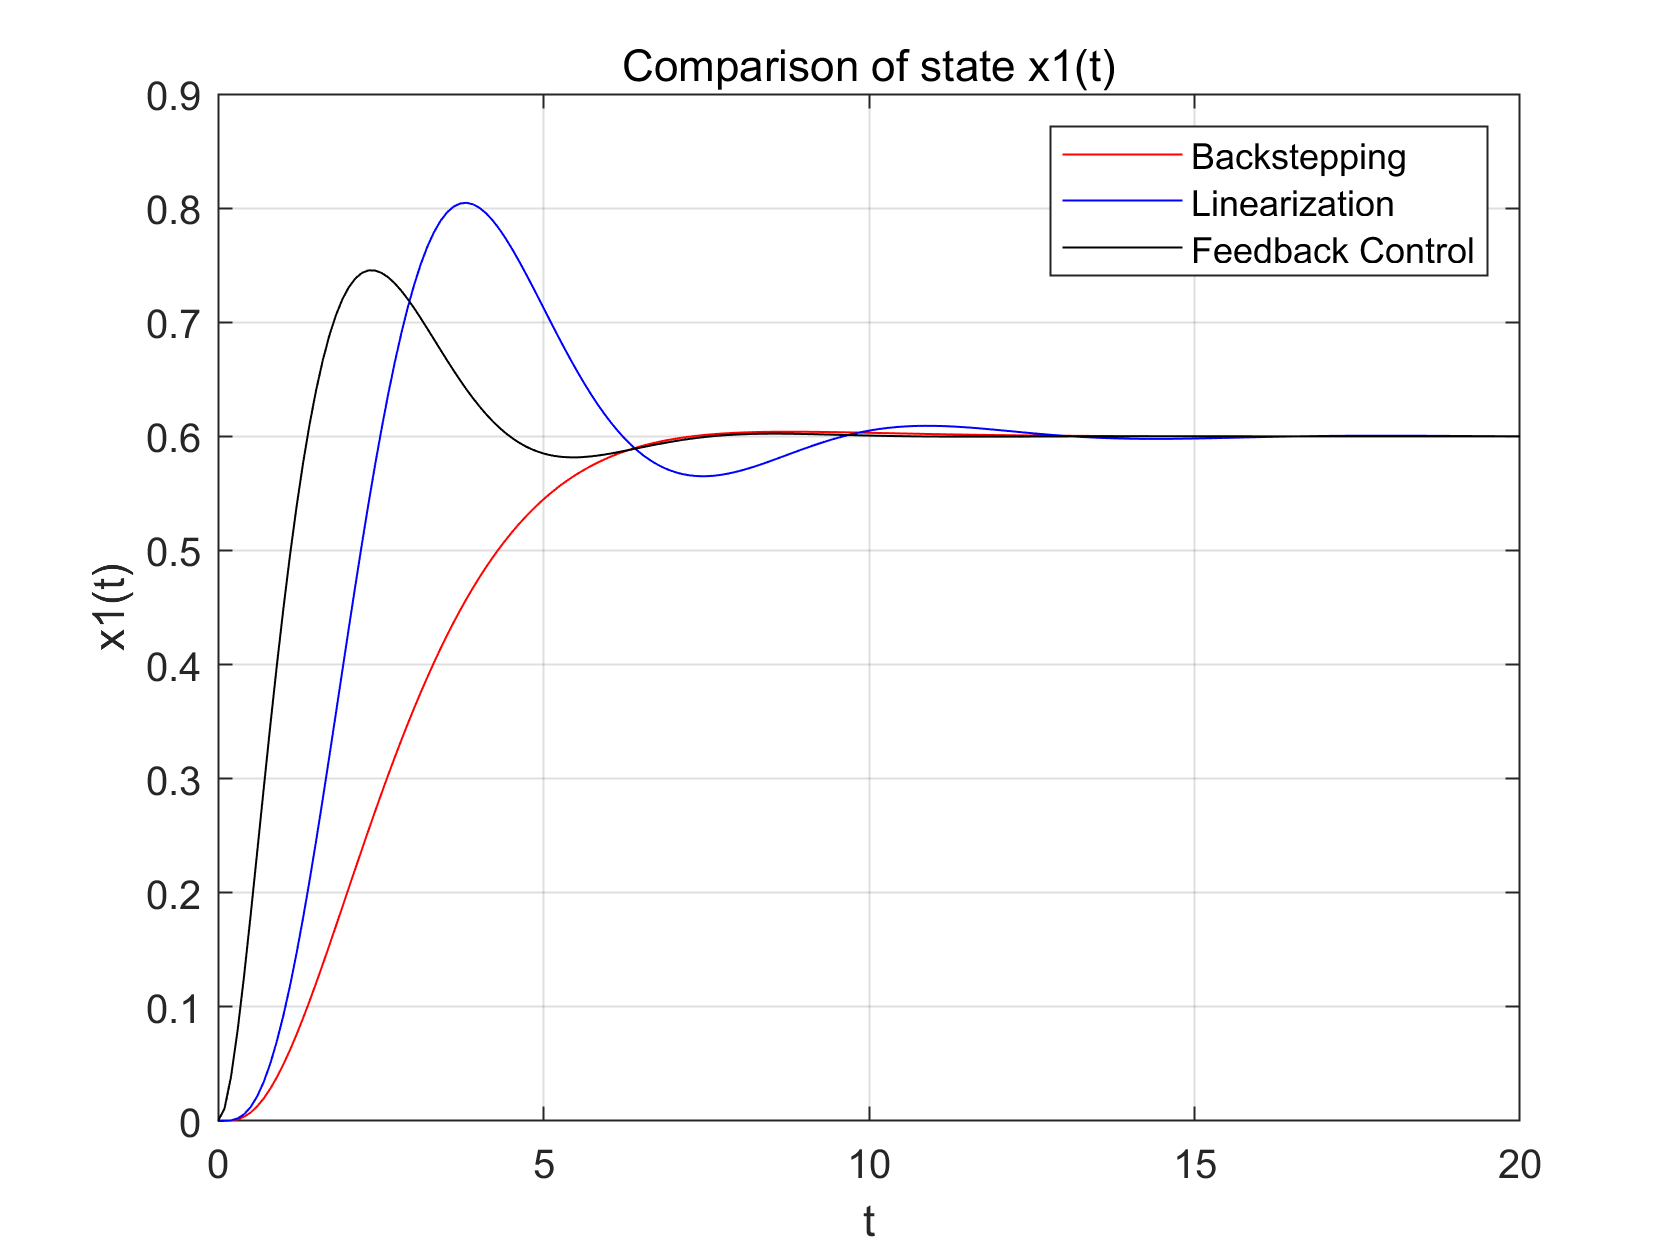



   figure(5)
 
plot(t,y1(1,:)+x1s,'-r');
hold on
plot(t,y2(1,:)+x1s,'-b');
hold on
plot(t,y3(1,:)+x1s,'-k');
legend('Backstepping','Linearization','Feedback Control')
 title('Comparison of state x1(t)')
xlabel('t')
ylabel('x1(t)')
grid on;

Figure 7. The comparison of x(t) using different method.

function out = mysaturation(v, low, up)
if v > up
    out = up;
elseif v < low
    out = low;
else
    out = v;
end
end